# Fill Missing Values

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

x = [0 NaN 7 8 NaN 2 -3 NaN -8]

x =      0   NaN     7     8   NaN     2    -3   NaN    -8


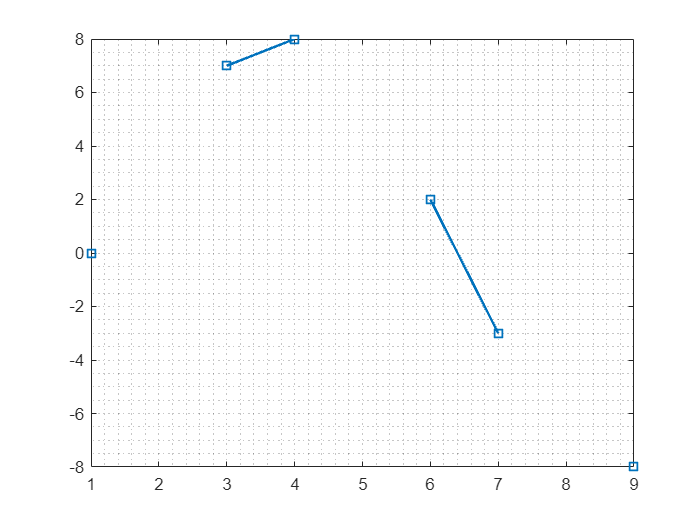

plot(x, "s-", "LineWidth", 1.5)
grid minor

## Task 1

A **Clean Missing Data** task has been added to the script `interpmethodsfill.mlx`. In this practice, you will use the task to interpolate missing data.

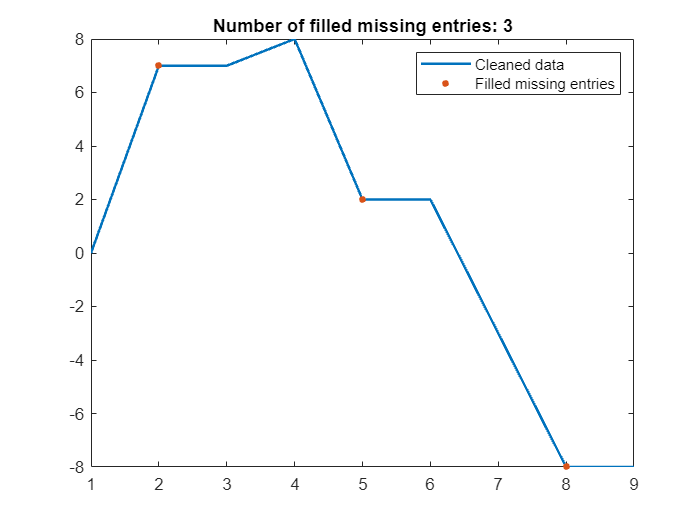

% Fill missing data
[y,missingIndices2] = fillmissing(x,"nearest");

% Display results
figure

% Plot cleaned data
plot(y,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices2),y(missingIndices2),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices2))

hold off
legend

clear missingIndices2

## Task 2

Click the triangle to view the code that interpolates missing data then plots it.

The first command fills the missing data.

z = fillmissing(x, "linear");

## Task 3

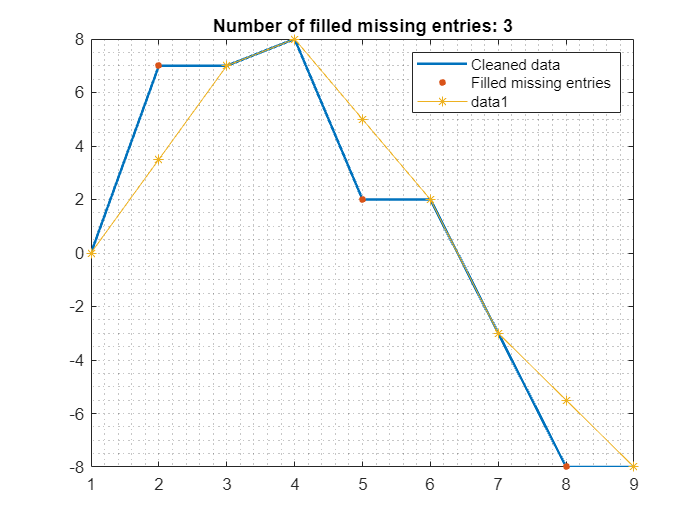

hold on
plot(z, "*-")
grid minor
hold off